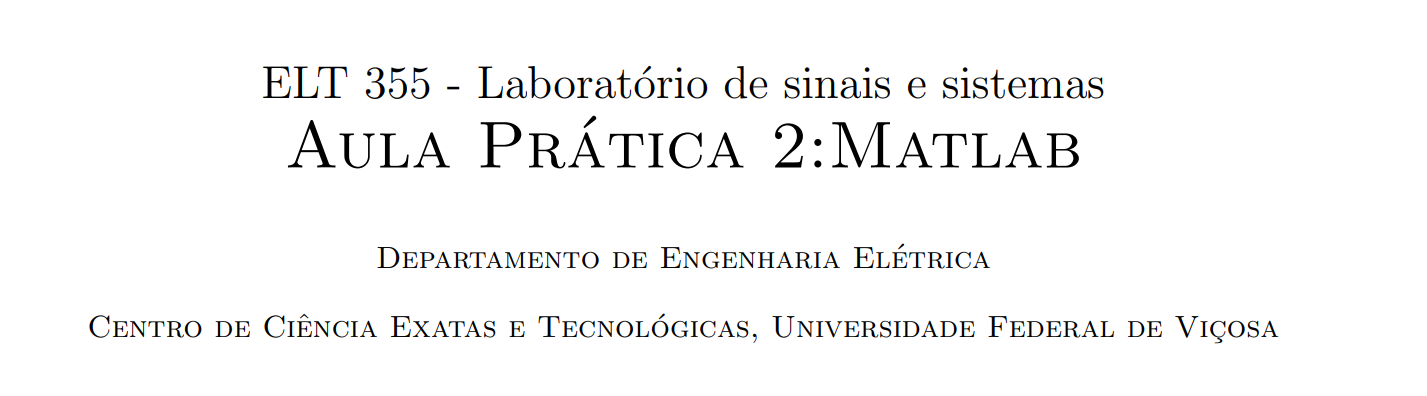

12/05/2022

**Aluno:** Déric A. F. de Sales - 96718

clear all; close all; clc;

Operações com vetores

x = 0:0.2:3;
y = exp(-x) + sin(x);

y =     1.0000    1.0174    1.0597    1.1135    1.1667    1.2094    1.2332    1.2320    1.2015    1.1391    1.0446    0.9193    0.7662    0.5898    0.3958    0.1909


z = [x' y']

z =          0    1.0000
    0.2000    1.0174
    0.4000    1.0597
    0.6000    1.1135
    0.8000    1.1667
    1.0000    1.2094
    1.2000    1.2332
    1.4000    1.2320
    1.6000    1.2015
    1.8000    1.1391


Trabalhando com a concatenação e secção de matrizes 

A = [123; 456; 789];
r = [13325];
A = [A; r]

A =          123
         456
         789
       13325



matriz6x6 = randi(10,6,6)

matriz6x6 =      3     3     5     4     3     4
     1    10     3     8     6     1
     4     9    10     7    10     8
     5     4     2     2     9     2
     4     5     9    10     5     4
     3     6     1     6     5     4


matriz2x2 = matriz6x6(2:3, 3:4)

matriz2x2 =      3     8
    10     7


Função que retorna o resultado de um polinômio cúbico

Sendo que:


$$y = f(x) = ax^3 + bx^2 + cx + d$$


%{
function y = resPolinomio(x,a,b,c,d)

y = 15

    y = a*(x^3) + b*(x^2) + c*x + d;
end 
%}

y = resPolinomio(1,2,3,4,6)

x =      1     2     3     4     5     6     7     8     9    10


Teste de expressões

No Matlab para realizar operações termo a termo das matrizes, usa-se o ponto " . " antes do operador para denotar a operação. Então, fazendo A.*B, o elemento de linha m e coluna n (elemento mn) da matriz A será multiplicado ao elemento mn da matriz B, e assim uma nova matriz será gerada com o resultado da operação. Para tal as matrizes devem ter as mesmas dimensões e as operações são válidas para diversos operadores do Matlab.

Assim, teremos que (x.^2) == (x.*x) será TRUE para toda a extensão do vetor x:

x = 1:10

ans = 1×10 logical array
   1   1   1   1   1   1   1   1   1   1


(x.^2) == (x.*x)

A expressão A^2 == A.^2 por sua vez, resulta em erro, já que é possível elevar os elementos do vetor ao quadrado, usando o ponto antes do operador  " ^ ", mas não é possível elevar o vetor em si ao quadrado. Isso é  caracterizado como uma operação inválida.

A = [123; 456; 789]

A =    123
   456
   789


%A^2 == A.^2 % erro

A função any() é um análogo à uma porta lógica OR para um vetor de valores. Se qualquer valor do vetor for diferente de zero, sua saída será igual à 1, e caso contrário, 0.

Já a função all() é análoga à porta lógica AND, seguindo a mesma lógica da função any().

(x.^3) > (3*x)

ans = 1×10 logical array
   0   1   1   1   1   1   1   1   1   1


any((x.^3) > (3*x))

ans = logical
   1



(x./(x+1)) > ((x+1)./(x+1.5))

ans = 1×10 logical array
   0   0   0   0   0   0   0   0   0   0


all( (x./(x+1)) > ((x+1)./(x+1.5)) )

ans = logical
   0


Uso de outras funções criadas

Calcula o fatorial de um dado número

fatorial(10)

ans = 3628800

Calcula a coma de duas matrizes

A1 = [23 45 76;
      36 87 22;
      89 74 16];
  
A2 = ones(3);

sumMatrix(A1,A2)

ans =     24    46    77
    37    88    23
    90    75    17


Calcula a multiplicação de duas matrizes

multMatrix(A1,A2)

ans =     23    45    76
    36    87    22
    89    74    16


#### Funções

*obs.: devem ser definidas no fim do script.*

function y = resPolinomio(x,a,b,c,d)
% Calcula o resultado do polinômio de 3ª ordem
    y = a*(x^3) + b*(x^2) + c*x + d;
end 

function res = fatorial(numero)
% Retorna o fatorial de um número inteiro
if floor(numero)~=ceil(numero)
    disp('O valor de entrada dado não é um número inteiro!') 
end
n = numero;
x = n;
while n ~= 1
    x = x*(n-1);
    n = n-1;
end
res = x;
end

function res = sumMatrix(A,B)
% Calcula a soma de duas matrizes.

res = A + B;

%aux = cat(3, A, B);
%res = sum(aux, 3);
end

function res = multMatrix(A,B)
% Calcula a multiplicação de duas matrizes
res = A.*B;
end